M = 10;
B = 11;
K = 120;

sys = tf(1, [M B K])

sys =
 
           1
  -------------------
  10 s^2 + 11 s + 120
 
Continuous-time transfer function.
Model Properties


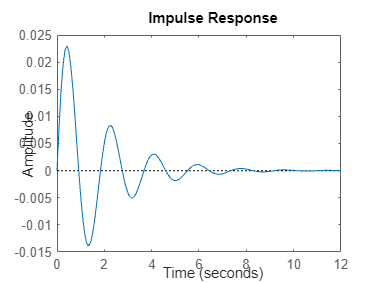

%roots([M B K])

impulse(sys)

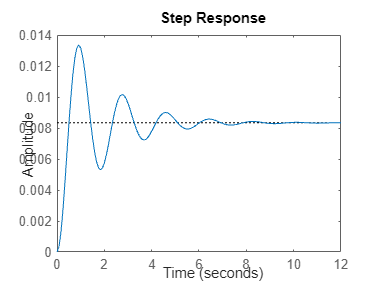

step(sys)


% sem controlador
sys_sem_cont = feedback(sys, 1)

sys_sem_cont =
 
           1
  -------------------
  10 s^2 + 11 s + 121
 
Continuous-time transfer function.
Model Properties


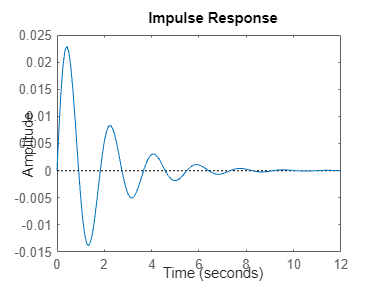

impulse(sys_sem_cont)

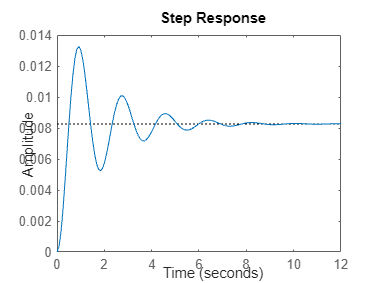

step(sys_sem_cont)

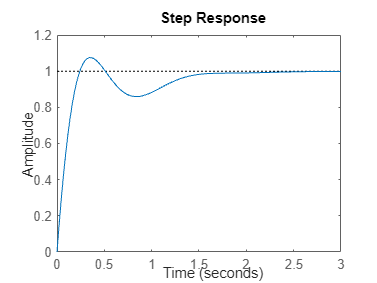


ki = 700;
kd = 70;
kp = 350;
T = 0.001;

% com controlador
controlador = tf([kd kp ki], [1 0]);
sys_com_cont = feedback(controlador * sys, 1);
step(sys_com_cont)


% tempo de estabelacimento: 1.47s
% overshoot: 7.51%
% tempo de subida: 0.176s